# TP2

## param & modeling

%il semble qu'analytique ne marche pas tres bien
% sym x;
% sym T;
% sym v;
% Pollution= @(x,v) x*v^2;
% T=@(x,v) 15-2*x/v;
% b=0.25*10^(-4);
% Profit=@(x,v) (15-2*x/v)*x-b*x*v^2;
% k=1;
% Risk=@(x,v) k*x;
clear
close all
x=50:50:1000

x =           50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000


v=25:25:500

v =     25    50    75   100   125   150   175   200   225   250   275   300   325   350   375   400   425   450   475   500


b=0.25*10^(-4);



## Q1 Profit


x=50:50:1400

x =           50         100         150         200         250         300         350         400         450         500         550         600         650         700         750         800         850         900         950        1000        1050        1100        1150        1200        1250        1300        1350        1400


v=25:25:500

v =     25    50    75   100   125   150   175   200   225   250   275   300   325   350   375   400   425   450   475   500


v=v' %il faut transposer mais pas besoin de produit en croix

v =     25
    50
    75
   100
   125
   150
   175
   200
   225
   250


Profit=(15-2.*x./v).*x-b*x.*v.^2

Profit = 	1.0e+05 *

    0.0055    0.0070    0.0045   -0.0020   -0.0125   -0.0270   -0.0456   -0.0681   -0.0946   -0.1251   -0.1596   -0.1981   -0.2406   -0.2871   -0.3376   -0.3921   -0.4506   -0.5131   -0.5796   -0.6502   -0.7247   -0.8032   -0.8857   -0.9722   -1.0627   -1.1572   -1.2557   -1.3582
    0.0065    0.0109    0.0134    0.0139    0.0123    0.0088    0.0033   -0.0043   -0.0138   -0.0253   -0.0388   -0.0544   -0.0719   -0.0914   -0.1130   -0.1365   -0.1620   -0.1896   -0.2191   -0.2506   -0.2842   -0.3197   -0.3572   -0.3967   -0.4383   -0.4818   -0.5273   -0.5749
    0.0068    0.0122    0.0163    0.0191    0.0205    0.0206    0.0193    0.0168    0.0129    0.0076    0.0011   -0.0068   -0.0161   -0.0267   -0.0386   -0.0518   -0.0664   -0.0823   -0.0995   -0.1181   -0.1380   -0.1592   -0.1818   -0.2057   -0.2309   -0.2575   -0.2854   -0.3146
    0.0069    0.0127    0.0176    0.0215    0.0244    0.0262    0.0271    0.0270    0.0259    0.0238    0.0206    0.0165    0.0114    0.

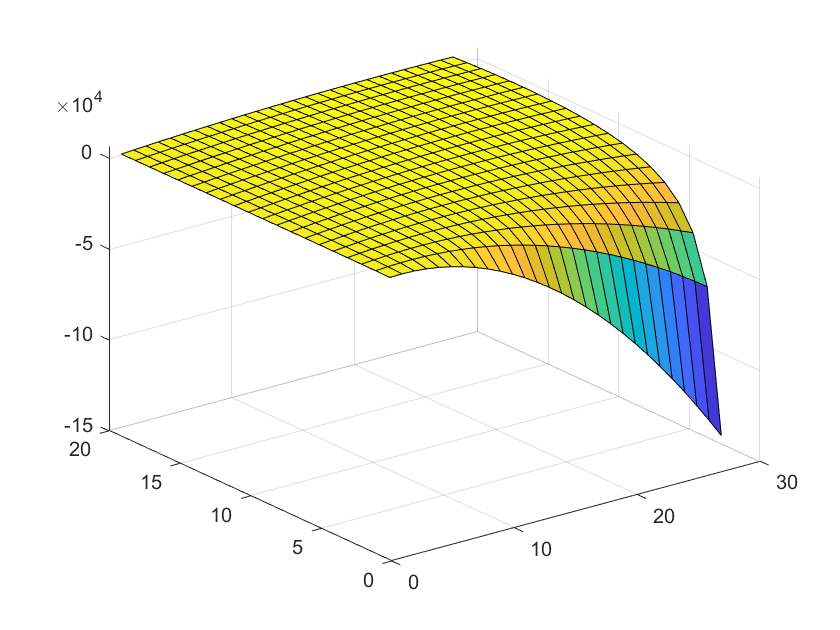

figure(1)
surf(Profit)

maxQ1=max(max(Profit))

maxQ1 = 6.2344e+03

[irow icol]=find(Profit==maxQ1)

irow = 14

icol = 21

% irow corresponds to v
% icol corresponds to x
disp(["The optimum value of distance x is " x(icol)])

    "The optimum value of distance x is "    "1050"



disp(["The optimum value of speed v is " v(irow)])

    "The optimum value of speed v is "    "350"



## Q2 Max Profit with given x

with given fishing zone x, find the max Profit with the optimum speed

clear
x=100; %a given number of distance
b=0.25*10^(-4);
v=25:5:500;
temp=ones(1,length(v))*100;
Profit=(15-2.*temp./v).*temp-b.*temp.*v.^2

Profit = 	1.0e+03 *

    0.6984    0.8311    0.9255    0.9960    1.0505    1.0938    1.1288    1.1577    1.1817    1.2020    1.2193    1.2340    1.2466    1.2575    1.2669    1.2750    1.2820    1.2879    1.2930    1.2973    1.3009    1.3039    1.3063    1.3081    1.3095    1.3104    1.3109    1.3110    1.3107    1.3101    1.3092    1.3079    1.3063    1.3045    1.3024    1.3000    1.2974    1.2945    1.2914    1.2881    1.2845    1.2808    1.2768    1.2727    1.2683    1.2637    1.2590    1.2541    1.2490    1.2437


disp(["for the given distance x=" x "the optimum speed is" v(find(Profit==max(Profit)))])

    "for the given distance x="    "100"    "the optimum speed is"    "160"



## Q3 Pareto

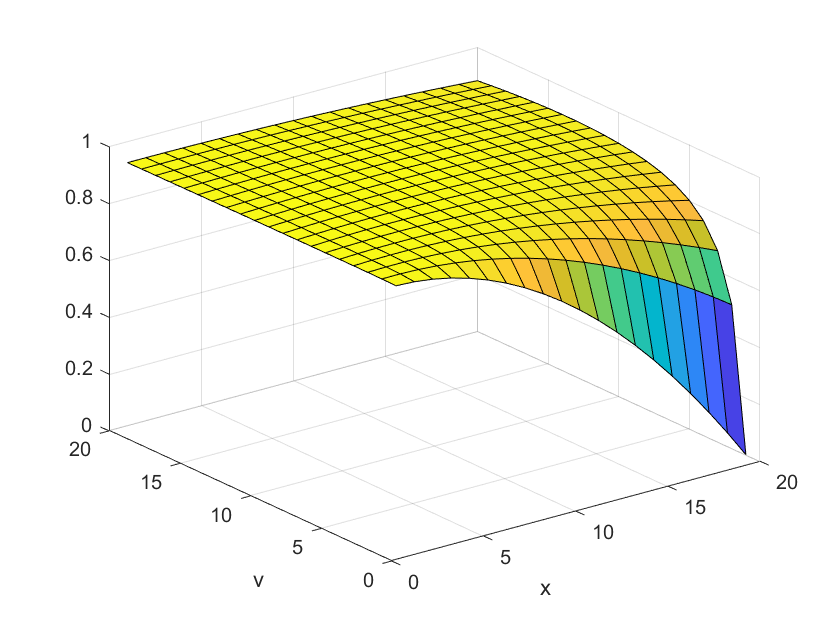

clear
% hi user, give some values
weightProfit= 0.9; %give a number between 0 and 1

% stop reading user, you need to turn on developper mode to continue
%param
weightRisk=1-weightProfit;
k=1;
b=0.25*10^(-4);

x=50:50:1000;
v=25:25:500;
%compute Profit and Risk
Profit=(15-2.*x./v').*x-b*x.*v'.^2;
Risk=k*x.*ones(length(x))';
%make a comparison table with two pages,
%the first page is Profit, second page is Risk
comparison=zeros(length(x),length(x),2);
comparison(:,:,1)=Profit;
comparison(:,:,2)=Risk;
%scale page 1 Profit
tempmin=min(min(comparison(:,:,1)));
tempmax=max(max(comparison(:,:,1)));
comparison(:,:,1)=(comparison(:,:,1)-tempmin)/(tempmax-tempmin);
%scale page 2 Risk
tempmin=min(min(comparison(:,:,2)));
tempmax=max(max(comparison(:,:,2)));
comparison(:,:,2)=(comparison(:,:,2)-tempmin)/(tempmax-tempmin);
%min and max trick, max the mark of Risk
comparison(:,:,2)=1-comparison(:,:,2);
%faire la poubelle
clearvars tempmax
clearvars tempmin

%give a final mark
partiel=comparison(:,:,1)*weightProfit+comparison(:,:,2)*weightRisk;
figure(2)
surf(partiel)
xlabel('x')
ylabel('v')

%whos the good student
[irow icol]=find(partiel==max(max(partiel)))

irow = 9

icol = 6

%irow for v, icol for x
disp(["The best speed is" v(irow)])

    "The best speed is"    "225"



disp(["The best distance is" x(icol)])

    "The best distance is"    "300"



## Q4 given speed, find distance

clear
% hi user, give some values
v=100; %give a value between 25 and 500
stepx=50;

% Administration permissoin required to continue reading
%param
k=1;
b=0.25*10^(-4);
x=50:stepx:1000;
temp=ones(1,length(x))*v;
Profit=(15-2.*x./temp).*x-b.*x.*temp.^2

Profit = 	1.0e+03 *

    0.6875    1.2750    1.7625    2.1500    2.4375    2.6250    2.7125    2.7000    2.5875    2.3750    2.0625    1.6500    1.1375    0.5250   -0.1875   -1.0000   -1.9125   -2.9250   -4.0375   -5.2500


[irow,icol]=findGoodStudent(Profit,2)

irow = 1

icol = 7

disp(["The best distance is" x(icol)])

    "The best distance is"    "350"



disp(["The best speed is" v(irow)])

    "The best speed is"    "100"



## Q5 link with Q3, still with x and v

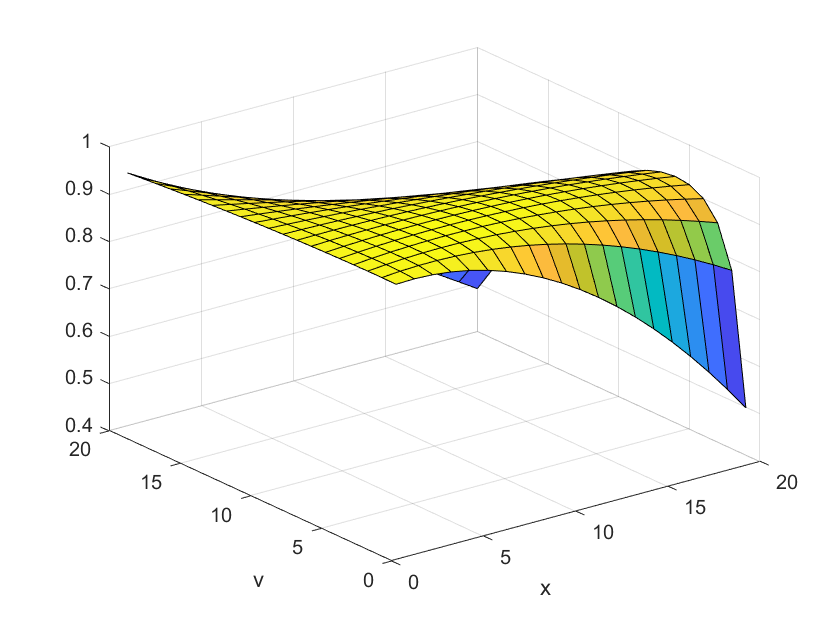

clear
% hi user, give some values
weightProfit= 0.5; %give a number between 0 and 1

% stop reading, i'm sleepy
weightPollution=1-weightProfit;
b=0.25*10^(-4);
%the dimensions of x and v must agree
x=50:50:1000;
v=25:25:500;
%compute Profit and Risk
Profit=(15-2.*x./v').*x-b*x.*v'.^2;
Pollution=x.*v'.^2;

%make a comparison table with two pages,
%the first page is Profit, second page is Risk
comparison=zeros(length(x),length(x),2);
comparison(:,:,1)=Profit;
comparison(:,:,2)=Pollution;
%scale page 1 Profit
tempmin=min(min(comparison(:,:,1)));
tempmax=max(max(comparison(:,:,1)));
comparison(:,:,1)=(comparison(:,:,1)-tempmin)/(tempmax-tempmin);
%scale page 2 Risk
tempmin=min(min(comparison(:,:,2)));
tempmax=max(max(comparison(:,:,2)));
comparison(:,:,2)=(comparison(:,:,2)-tempmin)/(tempmax-tempmin);
%min and max trick, now we find the max of mark of Pollution
comparison(:,:,2)=1-comparison(:,:,2);
%faire la poubelle
clearvars tempmax
clearvars tempmin

%give a final mark
partiel=comparison(:,:,1)*weightProfit+comparison(:,:,2)*weightPollution;
figure(3)
surf(partiel)
xlabel('x')
ylabel('v')

%whos the good student
[irow icol]=findGoodStudent(partiel,2)

irow = 4

icol = 6

%irow for v, icol for x
disp(["The best speed is" v(irow)])

    "The best speed is"    "100"



disp(["The best distance is" x(icol)])

    "The best distance is"    "300"



## Test

## fct

function [irow,icol] = findGoodStudent(matrix,Arg2)
%find the max or min value of a matrix, returns the row and column indice
%   arg1 is the matrix, arg2 is min or max, 1 for min, 2 for max
    
    if Arg2==1
        [irow,icol]=find(matrix==min(min(matrix)));
    
    elseif Arg2==2 
        [irow,icol]=find(matrix==max(max(matrix)));
    else 
        disp("The 2e argument must be 1 or 2, 1 for min, 2 for max")
    end
end